# Trabajo práctico: Filtrado digital FIR

## 5) Filtrado por ventanas con floating point en C

Se pretende ejecutar desde MATLAB una función descripta en C que implementa un filtro FIR (versión offline) en el dominio de la frecuencia. Se propone el siguiente ejemplo.

Se cuenta con una señal compuesta por un tono de 200 Hz y otro de 600 Hz, que ha sido corrompida por una señal de 50 Hz (frecuencia de línea eléctrica). Se desea diseñar un filtro pasa-banda que rechace la señal de 50 Hz y que deje pasar los dos tonos.

Se diseña un filtro pasa-banda con filterDesigner con frecuencias de corte 100 Hz y 800 Hz tipo Kaiser con beta igual a 5 y de orden 100. La frecuencia de muestreo es de 10 kHz.

Los coeficientes del filtro FIR se exportan (Targets/Generate C Header) al archivo fir_coefs.h en formato punto flotante, precisión simple.

Ejecute los siguientes pasos:

### a) Compile en MATLAB las funciones fir_filter.c y fir_matlab_wrapper.c con el comando:

fir_matlab_wrapper.c construye la interfaz entre las variables del Workspace de MATLAB y los argumentos de entrada/salida de las funciones en C.

fir_filter.c contiene la función fir_filter_float(), la cual implementa la convolución off-line entre los coeficientes del filtro FIR y una señal de entrada, todo en formato punto flotante, precisión simple (float).

mex fir_matlab_wrapper.c fir_filter.c;

Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.


### b) Analice el código de la función fir_matlab_to_C.m y ejecútela. ¿Qué observa?

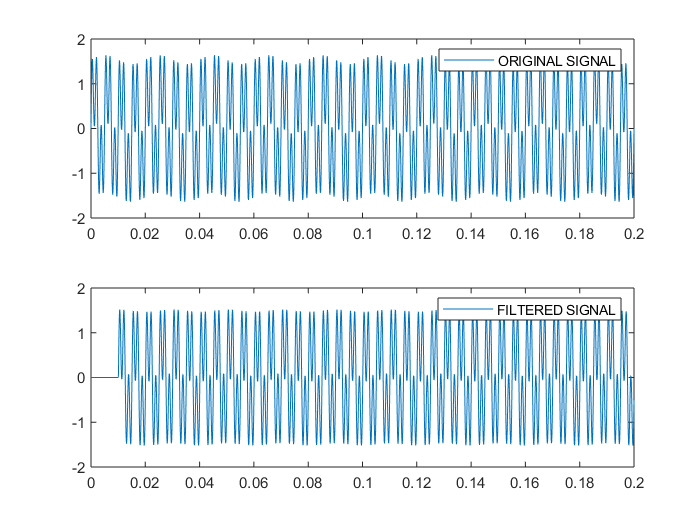

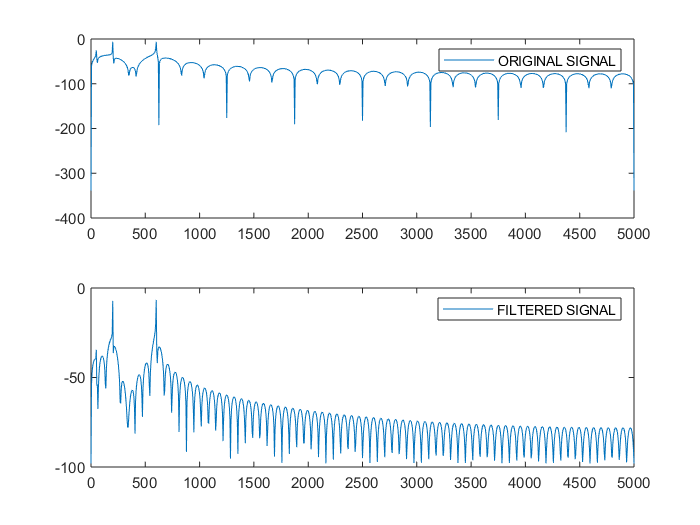

fir_matlab_to_C;

Se puede observar como el filtro eliminó practicamente la componente de 50 Hz no deseada.